b = 50; % baseline [mm]
f_6 = 6; % focal length [mm]
f_10 = 10; % focal length [mm]
ps = .006; % pixel size [mm]
xNumPix = 752; % total number of pixels in x direction of the sensor [px]
cxLeft = xNumPix/2; % left camera x center [px]
cxRight = xNumPix/2; % right camera x center [px]

% set up two cameras with focal length of 6 mm
camLeft_6 = CentralCamera(...
    'focal', f_6, ...
    'pixel', ps, ...
    'resolution', xNumPix,...
    'centre', cxLeft, ...
    'name', 'CameraLeft');

camRight_6 = CentralCamera(...
    'focal', f_6, ...
    'pixel', ps, ...
    'resolution', xNumPix,...
    'centre', cxRight, ...
    'name', 'CameraRight');

% set up two cameras with focal length of 10 mm
camLeft_10 = CentralCamera(...
    'focal', f_10, ...
    'pixel', ps, ...
    'resolution', xNumPix,...
    'centre', cxLeft, ...
    'name', 'CameraLeft');

camRight_10 = CentralCamera(...
    'focal', f_10, ...
    'pixel', ps, ...
    'resolution', xNumPix,...
    'centre', cxRight, ...
    'name', 'CameraRight');

% Set up camera positions
TcamL = SE3(-0.25, 0, 0);
TcamR = SE3(+0.25, 0, 0);
camLeft_6.T = TcamL;
camRight_6.T = TcamR;
camLeft_10.T = TcamL;
camRight_10.T = TcamR;

% Preallocate for camera projections
xLeft_6 = zeros(2, 100); 
xRight_6 = zeros(2, 100); 
xLeft_10 = zeros(2, 100); 
xRight_10 = zeros(2, 100);

% Varying Depth calculations
x = 1;
for i = 0:100
    PointPos = [1, 0, i]';
    xLeft_6(1:2,x) = camLeft_6.project(PointPos);
    xRight_6(1:2,x) = camRight_6.project(PointPos);
    xLeft_10(1:2,x) = camLeft_10.project(PointPos);
    xRight_10(1:2,x) = camRight_10.project(PointPos);
    x = x + 1;
end

% calculate depth and disparity
d_6 = (abs((xLeft_6-cxLeft)-(xRight_6-cxRight))*ps) % disparity [mm]

d_6 =        NaN    3.0000    1.5000    1.0000    0.7500    0.6000    0.5000    0.4286    0.3750    0.3333    0.3000    0.2727    0.2500    0.2308    0.2143    0.2000    0.1875    0.1765    0.1667    0.1579    0.1500    0.1429    0.1364    0.1304    0.1250    0.1200    0.1154    0.1111    0.1071    0.1034    0.1000    0.0968    0.0938    0.0909    0.0882    0.0857    0.0833    0.0811    0.0789    0.0769    0.0750    0.0732    0.0714    0.0698    0.0682    0.0667    0.0652    0.0638    0.0625    0.0612
       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Z_6 = ((b .* f_6) ./ d_6) ./ 100 % depth [m]

Z_6 =        NaN    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000   31.0000   32.0000   33.0000   34.0000   35.0000   36.0000   37.0000   38.0000   39.0000   40.0000   41.0000   42.0000   43.0000   44.0000   45.0000   46.0000   47.0000   48.0000   49.0000
       NaN       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf   

d_10 = (abs((xLeft_10-cxLeft)-(xRight_10-cxRight))*ps) % disparity [mm]

d_10 =        NaN    5.0000    2.5000    1.6667    1.2500    1.0000    0.8333    0.7143    0.6250    0.5556    0.5000    0.4545    0.4167    0.3846    0.3571    0.3333    0.3125    0.2941    0.2778    0.2632    0.2500    0.2381    0.2273    0.2174    0.2083    0.2000    0.1923    0.1852    0.1786    0.1724    0.1667    0.1613    0.1562    0.1515    0.1471    0.1429    0.1389    0.1351    0.1316    0.1282    0.1250    0.1220    0.1190    0.1163    0.1136    0.1111    0.1087    0.1064    0.1042    0.1020
       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Z_10 = ((b .* f_10) ./ d_10) ./ 100 % depth [m]

Z_10 =        NaN    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000   31.0000   32.0000   33.0000   34.0000   35.0000   36.0000   37.0000   38.0000   39.0000   40.0000   41.0000   42.0000   43.0000   44.0000   45.0000   46.0000   47.0000   48.0000   49.0000
       NaN       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf  


% calculate depth error
Z_original = zeros(2, 1000);
Z_original = 0:100;
depthError_6 = (Z_original - Z_6) ./ Z_original

depthError_6 = 1.0e-14 *

       NaN         0         0   -0.0148         0         0    0.0444   -0.0634         0    0.0789         0   -0.0161    0.0444   -0.0137    0.0127   -0.0474         0   -0.1254   -0.0197    0.0187         0   -0.0677    0.0969   -0.2008   -0.0888         0   -0.0137    0.0789    0.1903   -0.0123    0.1184   -0.0115         0   -0.1507   -0.1254   -0.0609    0.1776    0.2304   -0.1870   -0.0182         0   -0.0693    0.2030   -0.2313    0.0969   -0.2211    0.0618    0.1965    0.1776    0.0870
       NaN      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf   

depthError_10 = (Z_original - Z_10) ./ Z_original

depthError_10 = 1.0e-13 *

       NaN    0.0011         0   -0.0015   -0.0044   -0.0018    0.0015   -0.0013    0.0067    0.0020    0.0053    0.0145    0.0089    0.0068    0.0102    0.0071    0.0067    0.0084   -0.0099   -0.0131   -0.0089   -0.0102   -0.0161   -0.0015   -0.0148   -0.0242   -0.0191   -0.0171   -0.0190   -0.0270   -0.0225   -0.0011   -0.0133   -0.0086   -0.0042   -0.0305   -0.0217   -0.0192         0   -0.0036   -0.0089    0.0225    0.0169    0.0446    0.0291    0.0411    0.0278    0.0181    0.0178    0.0334
       NaN      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf  

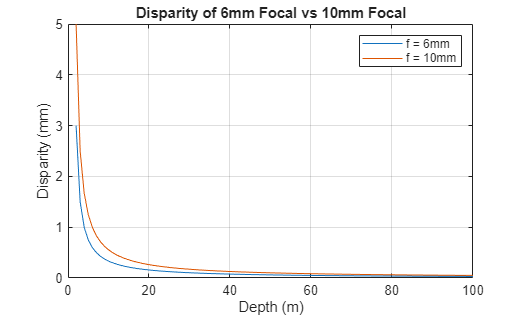


% plot disparity
plot(d_6(1,:));
xlabel('Depth (m)');
ylabel('Disparity (mm)');
grid on;
hold on;
xlim([0 100]);
ylim("auto");
title("Disparity of 6mm Focal vs 10mm Focal")
plot(d_10(1, :));
legend('f = 6mm', 'f = 10mm');
hold off;

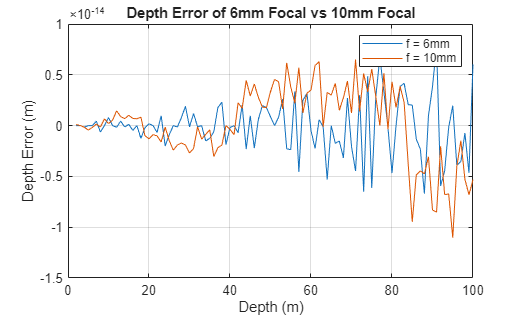


% plot depth error
plot(depthError_6(1,:));
xlabel('Depth (m)');
ylabel('Depth Error (m)');
grid on;
hold on;
xlim([0 100]);
ylim("auto");
title("Depth Error of 6mm Focal vs 10mm Focal");
plot(depthError_10(1, :));
legend('f = 6mm', 'f = 10mm');